# **Illustrate stability concepts in time series**

- **Null Hypothesis (H0): The time series has a unit root (it is non-stationary).**

- **Mathematical Form**: ϕ=1

- This hypothesis suggests that the time series is a random walk. If the time series has a unit root, it means that any shocks or changes in the series will have a permanent effect and the series will not revert to a long-term average. Essentially, the series is not predictable and keeps wandering over time.

- **Alternative Hypothesis (H1): The time series does not have a unit root (it is stationary).**

- **Mathematical Form**: ϕ<1

- **Overview: **This hypothesis suggests that the time series is stationary. If the time series does not have a unit root, it means that any shocks or changes in the series are temporary, and the series will eventually revert to a long-term average. The statistical properties of the series, like mean and variance, are constant over time, making it more predictable.

**Generate AR(1) process with different phi values**

n = 1000;
epsilon = randn(n, 1);

**Case 1: Stationary process (phi = 0.5)**

phi1 = 0.5;
y1 = zeros(n, 1);
for t = 2:n
    y1(t) = phi1 * y1(t-1) + epsilon(t);
end

**Case 2: Unit root process (phi = 1)**

phi2 = 1;
y2 = zeros(n, 1);
for t = 2:n
    y2(t) = phi2 * y2(t-1) + epsilon(t);
end

**Case 3: Explosive process (phi = 1.1)**

phi3 = 1.1;
y3 = zeros(n, 1);
for t = 2:n
    y3(t) = phi3 * y3(t-1) + epsilon(t);
end

**Plot the time series**

figure;
subplot(3,1,1);
plot(y1);
title('Stationary Process (\phi = 0.5)');
xlabel('Time');
ylabel('Value');

subplot(3,1,2);
plot(y2);
title('Unit Root Process (\phi = 1)');
xlabel('Time');
ylabel('Value');

subplot(3,1,3);
plot(y3);
title('Explosive Process (\phi = 1.1)');
xlabel('Time');
ylabel('Value');

**Testing Case 1: **(phi = 0.5)

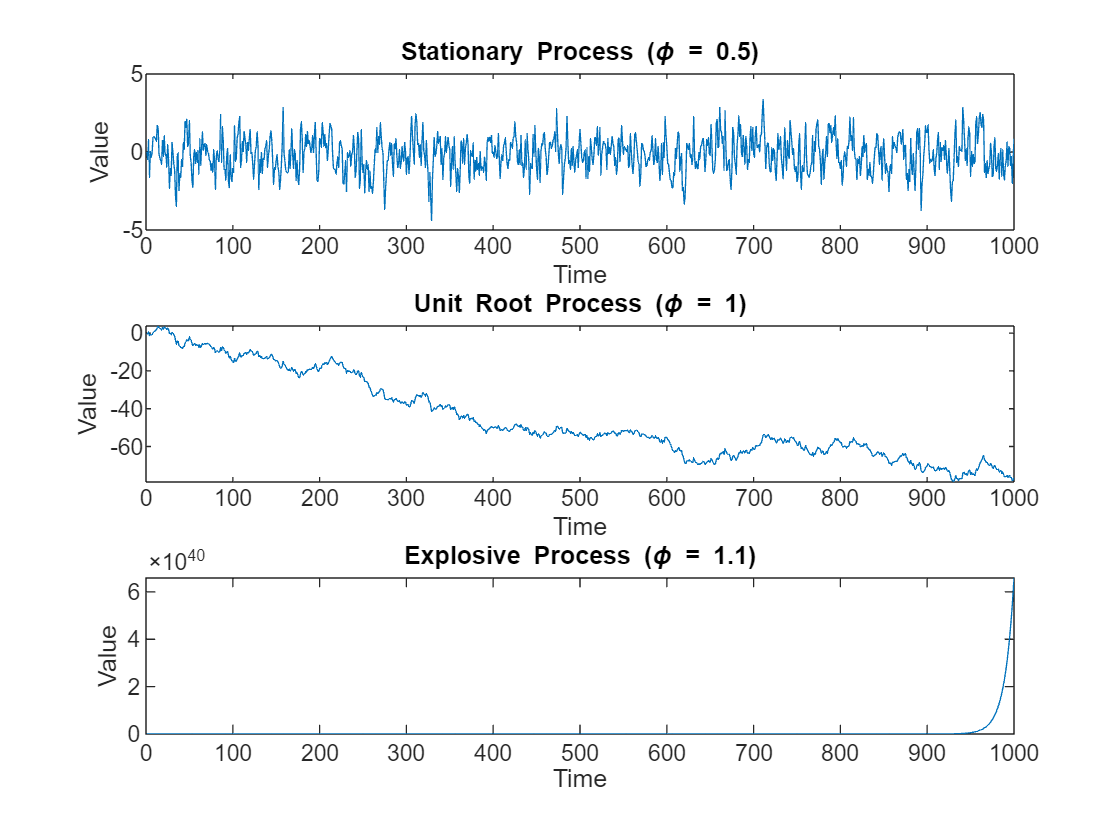

[h, pValue, stat, cValue] = adftest(y1);


% Display the results
disp(['ADF Test Hypothesis (h = 0: Has unit root, h = 1: Stationary): ', num2str(h)]);
disp(['P-value: ', num2str(pValue)]);

**Testing Case 2: **(phi = 1)

[h, pValue, stat, cValue] = adftest(y3);

% Display the results

ADF Test Hypothesis (h = 0: Has unit root, h = 1: Stationary): 1


disp(['ADF Test Hypothesis (h = 0: Has unit root, h = 1: Stationary): ', num2str(h)]);

P-value: 0.001


disp(['P-value: ', num2str(pValue)]);

**Testing Case 3: **(phi = 1.1)

[h, pValue, stat, cValue] = adftest(y2);

% Display the results

ADF Test Hypothesis (h = 0: Has unit root, h = 1: Stationary): 0


disp(['ADF Test Hypothesis (h = 0: Has unit root, h = 1: Stationary): ', num2str(h)]);

P-value: 0.999


disp(['P-value: ', num2str(pValue)]);

ADF Test Hypothesis (h = 0: Has unit root, h = 1: Stationary): 0


P-value: 0.88324
